### Global Variables

prec = 100;
digits(prec);

N_max = 10;
x = 20.0;

x_max = 20.0;
x_min = -20.0;
x_size = 100;

X = linspace(x_max,x_min,x_size);
x_axi_plot = linspace(0,N_max,N_max+1);

wavefunction_MATLAB_1_list = zeros(1,N_max+1);
wavefunction_Fast_Wave_smod_list = zeros(1,N_max+1);

wavefunction_MATLAB_1_2_list = zeros(1,N_max+1);
wavefunction_Fast_Wave_smmd_list = zeros(1,N_max+1);

wavefunction_MATLAB_3_list = zeros(1,N_max+1);
wavefunction_Fast_Wave_mmod_list = zeros(1,N_max+1);

wavefunction_MATLAB_4_list = zeros(1,N_max+1);
wavefunction_Fast_Wave_mmmd_list = zeros(1,N_max+1);

left = 0.08; 
bottom = 0.45; 
width = 0.4; 
height = 0.4;

### Tests

#### `Single-Mode and Onedimensional speed test`

import py.fast_wave.wavefunction.wavefunction_smod

Functionality Test Passed: True


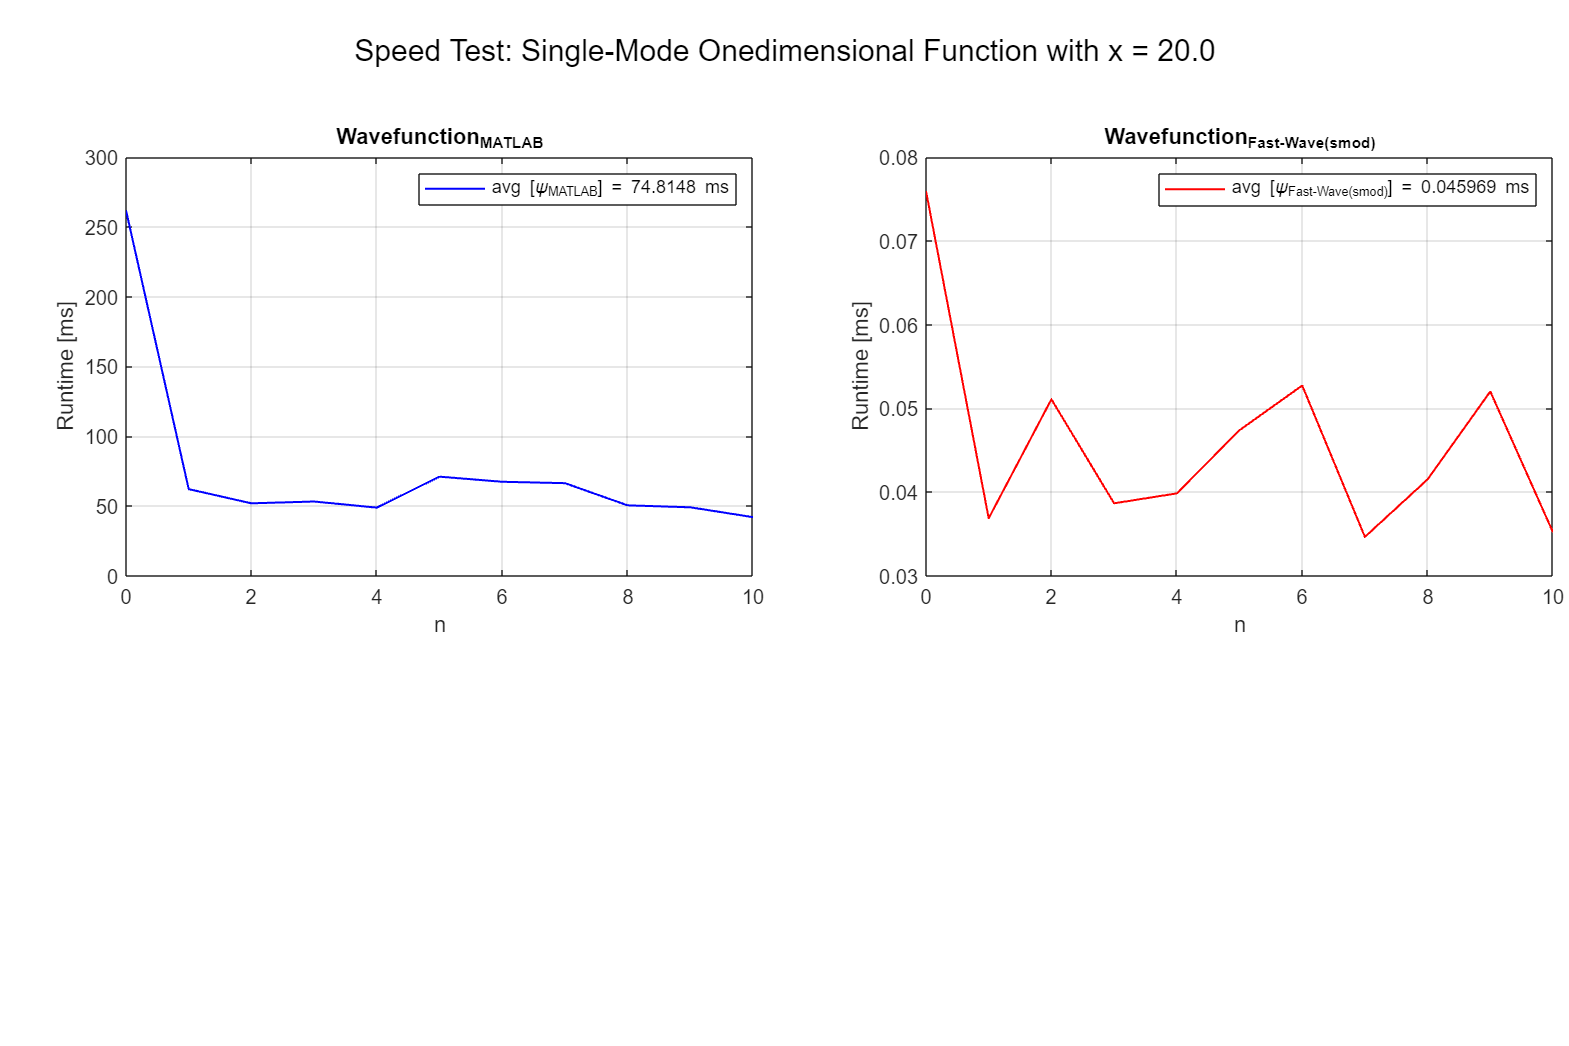


for n = 0:N_max
    f1 = @()(wavefunction_MATLAB_1(n,x,prec)); 
    f2 = @()(wavefunction_smod(uint64(n), x));
    exec_time_1 = timeit(f1) * 1000;
    exec_time_2 = timeit(f2) * 1000;
    wavefunction_MATLAB_1_list(n+1) = exec_time_1;
    wavefunction_Fast_Wave_smod_list(n+1) = exec_time_2;
end

figure('Position', [100, 100, 1200, 800]);
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_MATLAB_1_list, 'b-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
legend(sprintf('avg [\\psi_{MATLAB}] = '+ string(mean(wavefunction_MATLAB_1_list))+' ms'));
title('Wavefunction_{MATLAB}');

left = 0.59;
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_Fast_Wave_smod_list,'r-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
title('Wavefunction_{Fast-Wave(smod)}')
sgtitle('Speed Test: Single-Mode Onedimensional Function with x = 20.0');
legend(sprintf('avg [\\psi_{Fast-Wave(smod)}] = '+ string(mean(wavefunction_Fast_Wave_smod_list))+' ms'));

#### `Single-Mode and Onedimensional speed test (less_test)`

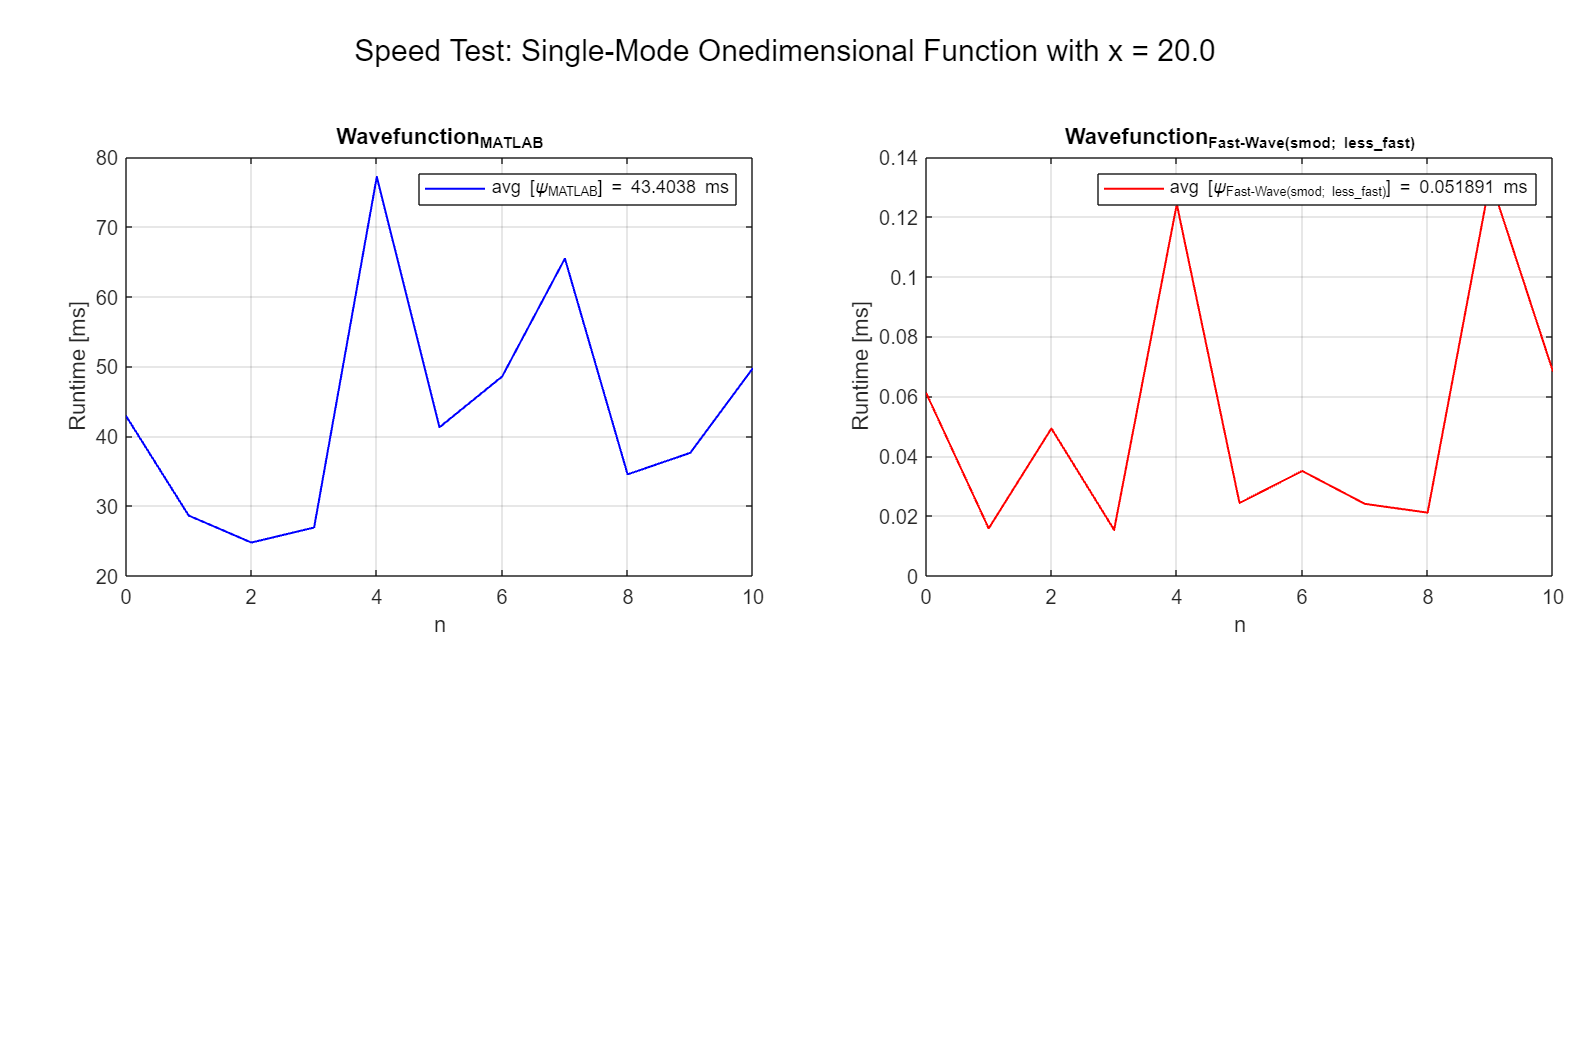

import py.fast_wave.wavefunction.wavefunction_smod

for n = 0:N_max
    f1 = @()(wavefunction_MATLAB_1(n,x,prec)); 
    f2 = @()(wavefunction_smod(uint64(n), x, more_fast=false));
    exec_time_1 = timeit(f1) * 1000;
    exec_time_2 = timeit(f2) * 1000;
    wavefunction_MATLAB_1_list(n+1) = exec_time_1;
    wavefunction_Fast_Wave_smod_list(n+1) = exec_time_2;
end

figure('Position', [100, 100, 1200, 800]);
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_MATLAB_1_list, 'b-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
legend(sprintf('avg [\\psi_{MATLAB}] = '+ string(mean(wavefunction_MATLAB_1_list))+' ms'));
title('Wavefunction_{MATLAB}');

left = 0.59;
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_Fast_Wave_smod_list,'r-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
title('Wavefunction_{Fast-Wave(smod; less\_fast)}');
sgtitle('Speed Test: Single-Mode Onedimensional Function with x = 20.0');
legend(sprintf('avg [\\psi_{Fast-Wave(smod; less\\_fast)}] = '+ string(mean(wavefunction_Fast_Wave_smod_list))+' ms'));

#### `Single-Mode and Multidimensional speed test`

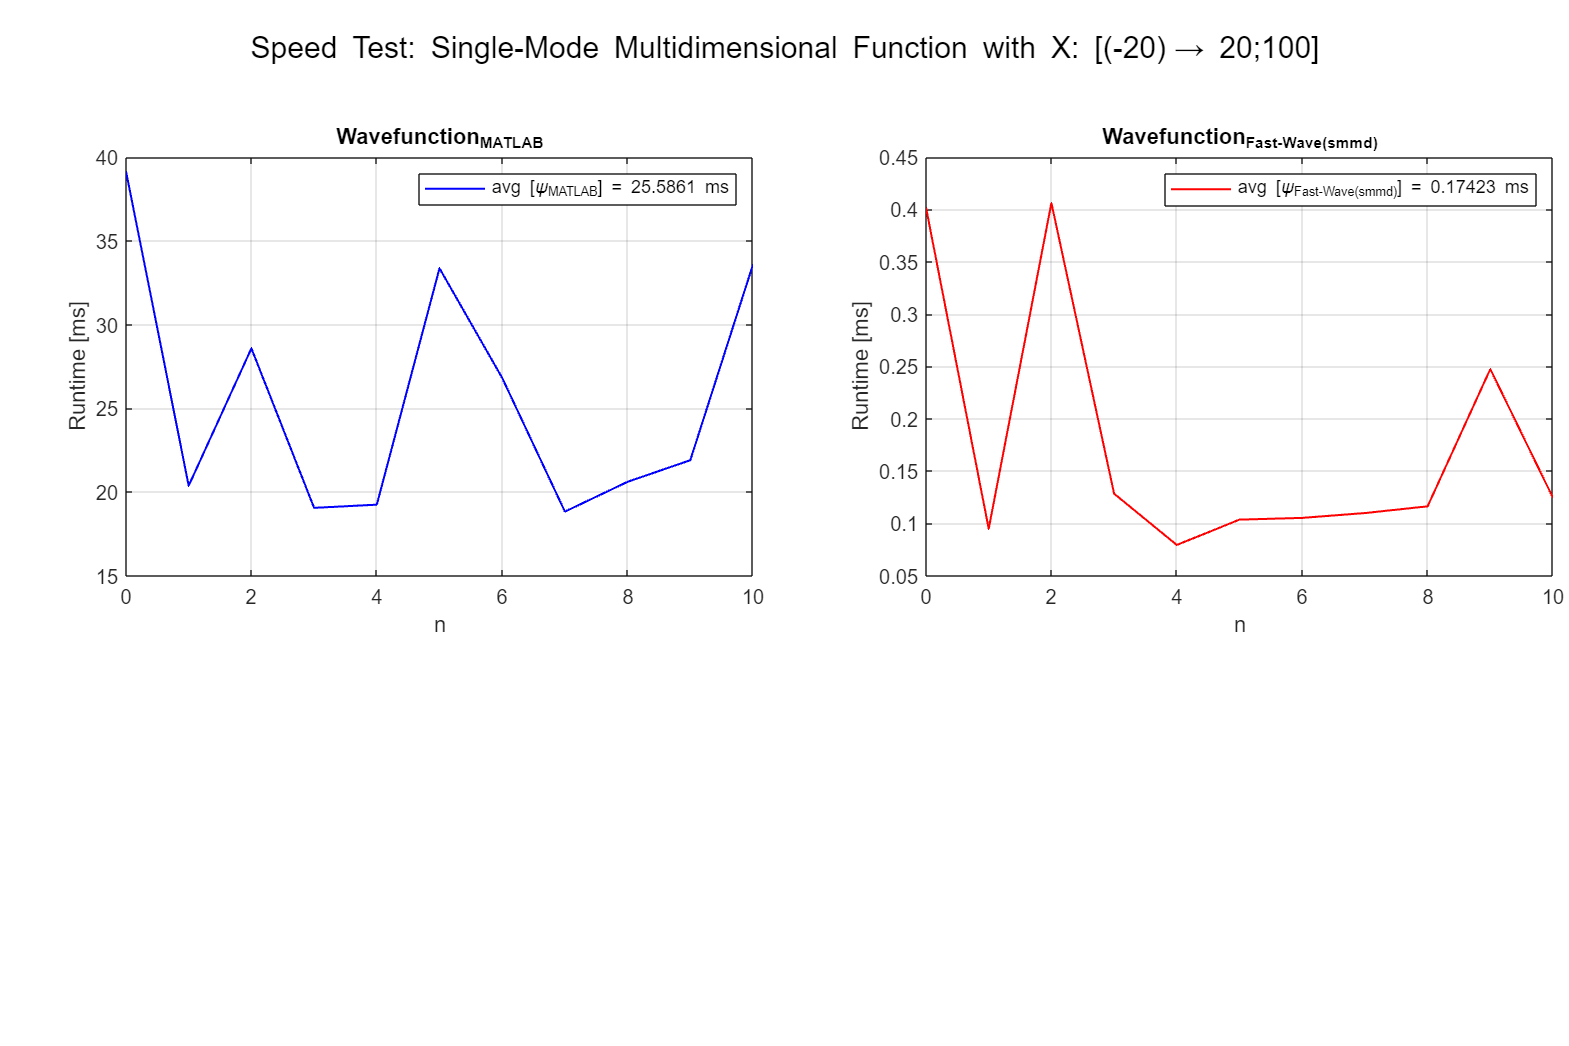

import py.fast_wave.wavefunction.wavefunction_smmd

left = 0.08; 

for n = 0:N_max
    f1 = @()(wavefunction_MATLAB_1(n,x,prec)); 
    f2 = @()(wavefunction_smmd(uint64(n), py.numpy.array(X)));
    exec_time_1 = timeit(f1) * 1000;
    exec_time_2 = timeit(f2) * 1000;
    wavefunction_MATLAB_1_2_list(n+1) = exec_time_1;
    wavefunction_Fast_Wave_smmd_list(n+1) = exec_time_2;
end

figure('Position', [50, 50, 1200, 800]);
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_MATLAB_1_2_list, 'b-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
legend(sprintf('avg [\\psi_{MATLAB}] = '+ string(mean(wavefunction_MATLAB_1_2_list))+' ms'));
title('Wavefunction_{MATLAB}');

left = 0.59;
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_Fast_Wave_smmd_list,'r-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
title('Wavefunction_{Fast-Wave(smmd)}');
sgtitle(sprintf('Speed Test: Single-Mode Multidimensional Function with X: [(-20)\\rightarrow 20;100]'));
legend(sprintf('avg [\\psi_{Fast-Wave(smmd)}] = '+ string(mean(wavefunction_Fast_Wave_smmd_list))+' ms')); 

#### `Single-Mode and Multidimensional speed test (less_fast)`

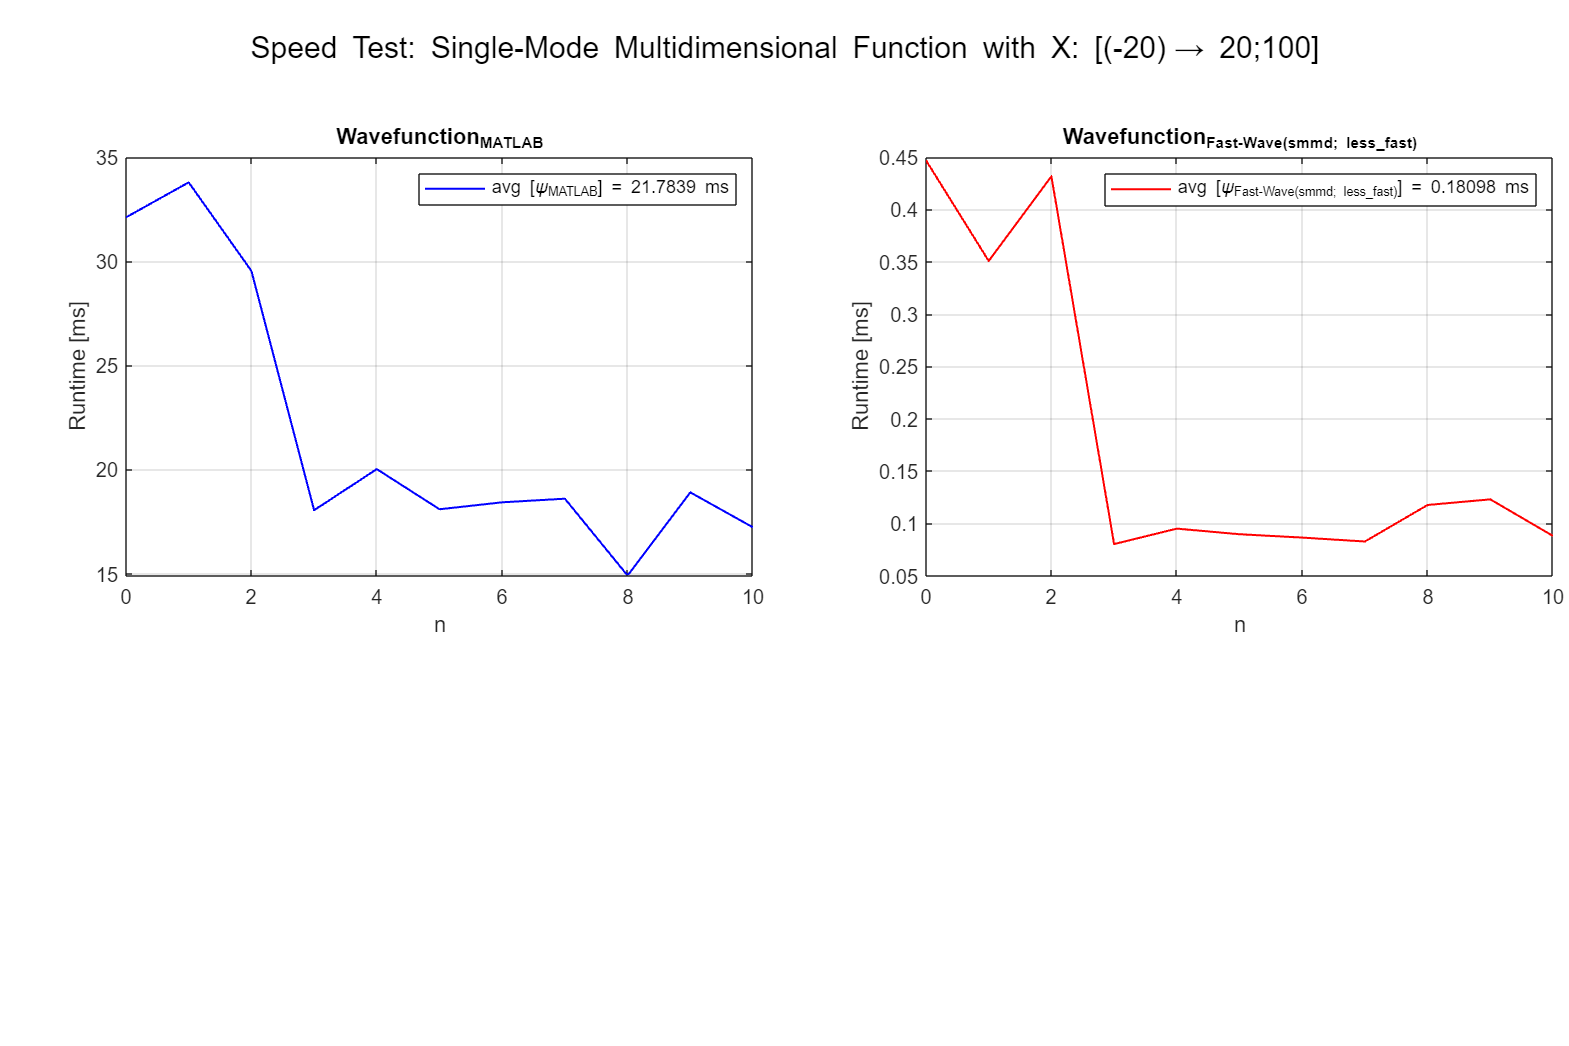

import py.fast_wave.wavefunction.wavefunction_smmd

left = 0.08; 

for n = 0:N_max
    f1 = @()(wavefunction_MATLAB_1(n,x,prec)); 
    f2 = @()(wavefunction_smmd(uint64(n), py.numpy.array(X), more_fast=false));
    exec_time_1 = timeit(f1) * 1000;
    exec_time_2 = timeit(f2) * 1000;
    wavefunction_MATLAB_1_2_list(n+1) = exec_time_1;
    wavefunction_Fast_Wave_smmd_list(n+1) = exec_time_2;
end

figure('Position', [50, 50, 1200, 800]);
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_MATLAB_1_2_list, 'b-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
legend(sprintf('avg [\\psi_{MATLAB}] = '+ string(mean(wavefunction_MATLAB_1_2_list))+' ms'));
title('Wavefunction_{MATLAB}');

left = 0.59;
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_Fast_Wave_smmd_list,'r-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
title('Wavefunction_{Fast-Wave(smmd; less\_fast)}');
sgtitle(sprintf('Speed Test: Single-Mode Multidimensional Function with X: [(-20)\\rightarrow 20;100]'));
legend(sprintf('avg [\\psi_{Fast-Wave(smmd; less\\_fast)}] = '+ string(mean(wavefunction_Fast_Wave_smmd_list))+' ms')); 

#### `Multi-Mode and Onedimensional speed test`

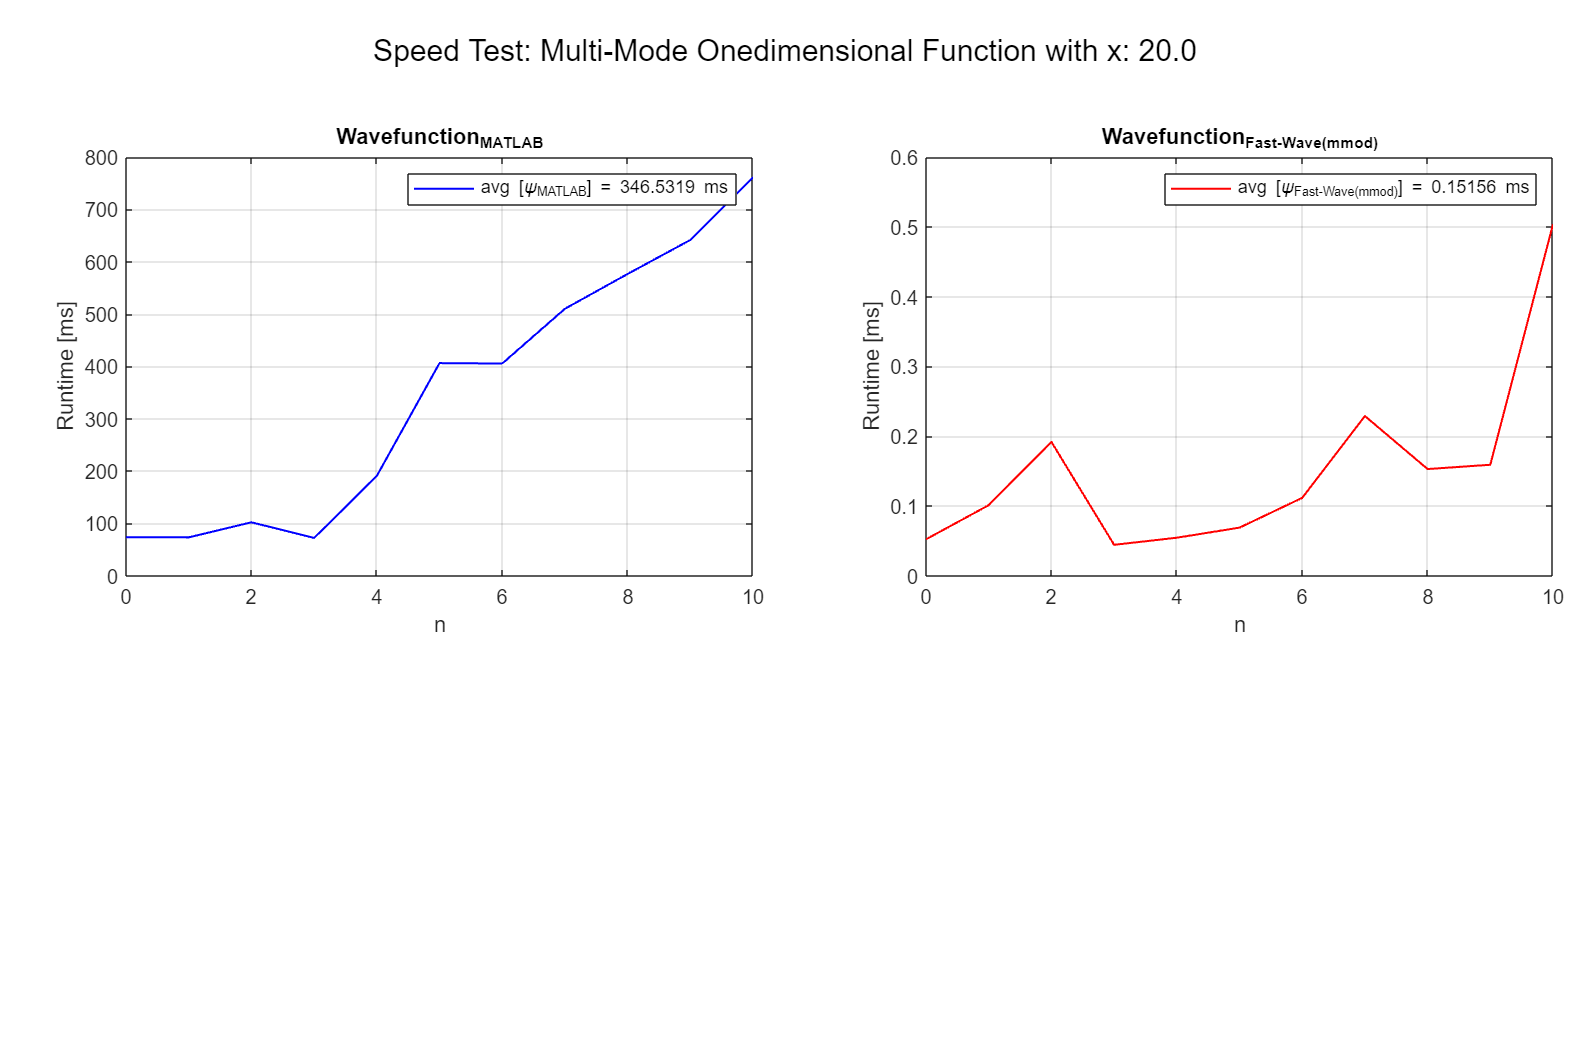

import py.fast_wave.wavefunction.wavefunction_mmod

left = 0.08; 

for n = 0:N_max
    f1 = @()(wavefunction_MATLAB_3(n,x,prec)); 
    f2 = @()(wavefunction_mmod(uint64(n),x));
    exec_time_1 = timeit(f1) * 1000;
    exec_time_2 = timeit(f2) * 1000;
    wavefunction_MATLAB_3_list(n+1) = exec_time_1;
    wavefunction_Fast_Wave_mmod_list(n+1) = exec_time_2;
end

figure('Position', [50, 50, 1200, 800]);
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_MATLAB_3_list, 'b-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
legend(sprintf('avg [\\psi_{MATLAB}] = '+ string(mean(wavefunction_MATLAB_3_list))+' ms'));
title('Wavefunction_{MATLAB}');

left = 0.59;
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_Fast_Wave_mmod_list,'r-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
title('Wavefunction_{Fast-Wave(mmod)}');
sgtitle(sprintf('Speed Test: Multi-Mode Onedimensional Function with x: 20.0'));
legend(sprintf('avg [\\psi_{Fast-Wave(mmod)}] = '+ string(mean(wavefunction_Fast_Wave_mmod_list))+' ms')); 

#### `Multi-Mode and Multidimensional speed test`

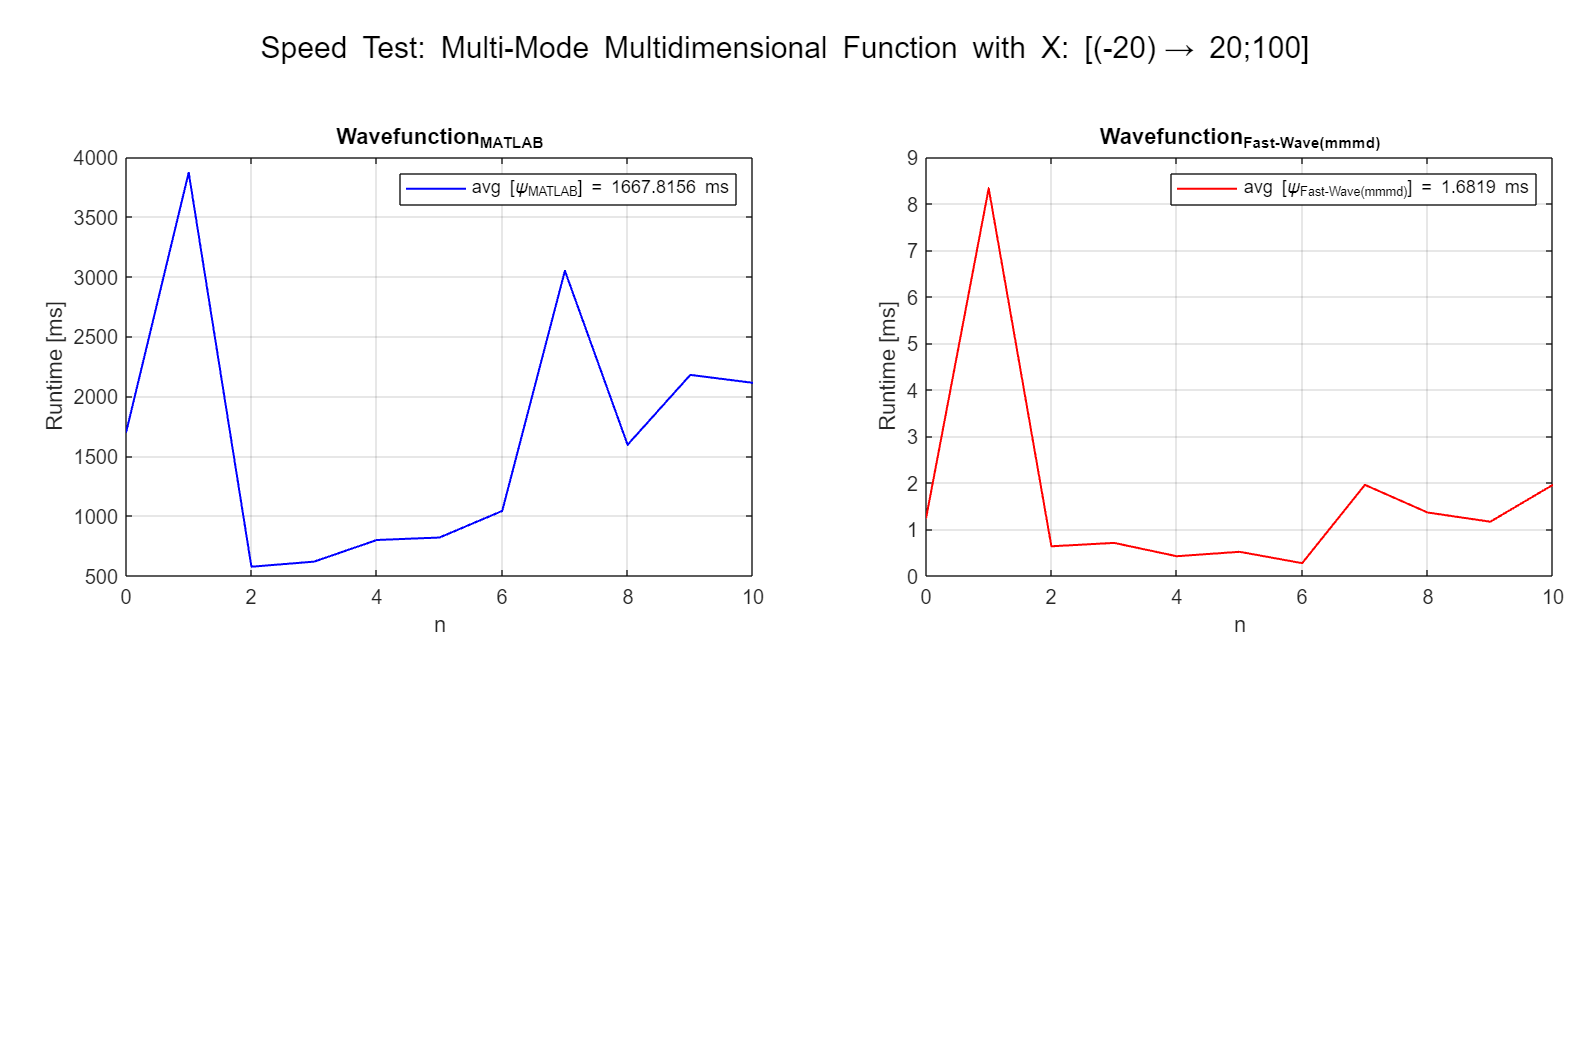

import py.fast_wave.wavefunction.wavefunction_mmmd

left = 0.08; 

for n = 0:N_max
    f1 = @()(wavefunction_MATLAB_4(n,X,prec)); 
    f2 = @()(wavefunction_mmmd(uint64(n),py.numpy.array(X)));
    exec_time_1 = timeit(f1) * 1000;
    exec_time_2 = timeit(f2) * 1000;
    wavefunction_MATLAB_4_list(n+1) = exec_time_1;
    wavefunction_Fast_Wave_mmmd_list(n+1) = exec_time_2;
end

figure('Position', [50, 50, 1200, 800]);
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_MATLAB_4_list, 'b-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
legend(sprintf('avg [\\psi_{MATLAB}] = '+ string(mean(wavefunction_MATLAB_4_list))+' ms'));
title('Wavefunction_{MATLAB}');

left = 0.59;
subplot('Position', [left bottom width height]);
plot(x_axi_plot, wavefunction_Fast_Wave_mmmd_list,'r-','LineWidth', 1); 
grid on;
xlabel('n');
ylabel('Runtime [ms]');
title('Wavefunction_{Fast-Wave(mmmd)}');
sgtitle(sprintf('Speed Test: Multi-Mode Multidimensional Function with X: [(-20)\\rightarrow 20;100]'));
legend(sprintf('avg [\\psi_{Fast-Wave(mmmd)}] = '+ string(mean(wavefunction_Fast_Wave_mmmd_list))+' ms')); 